# 変換としての行列(1)

clear;clc;close all

A=[1 2;2 1];
sym(A)

$$ans = \left(\begin{array}{cc} 1 & 2\\ 2 & 1 \end{array}\right)$$

x=[2;-1];
sym(x)

$$ans = \left(\begin{array}{c} 2\\ -1 \end{array}\right)$$

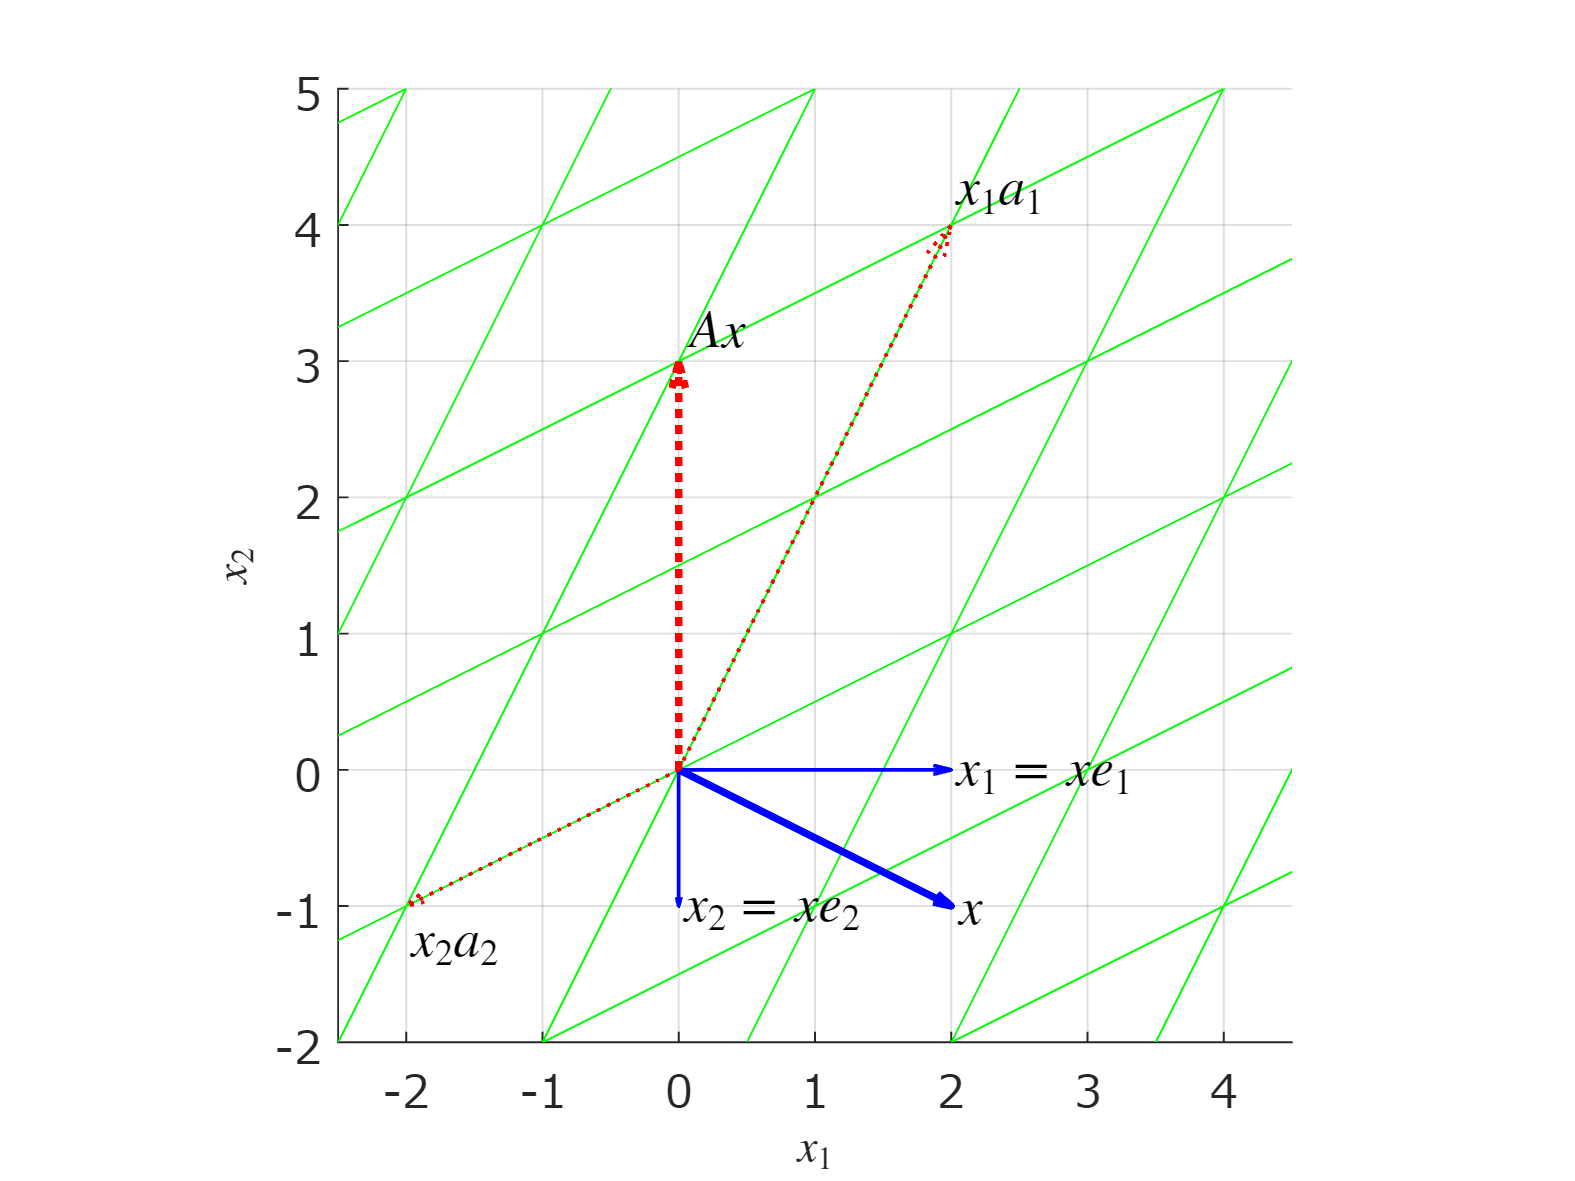


b=A*x;

figure;hold on;
set(gca,'fontname','メイリオ','fontsize',12);
X=zeros(9,9);
Y=zeros(9,9);
Z=zeros(9,9);
for n1=-4:4
    for n2=-4:4
        tmpV=n1*A(:,1)+n2*A(:,2);
        X(n1+5,n2+5)=tmpV(1);
        Y(n1+5,n2+5)=tmpV(2);
        Z(n1+5,n2+5)=0;
        
    end
end
mesh(X,Y,Z,'FaceAlpha',0,'EdgeColor','g');

grid on;axis equal;
axis([-2.5 4.5 -2 5]);
xticks(-3:5);yticks(-3:5);
quiver(0, 0, x(1), x(2),'b-','LineWidth',2,'AutoScale','off');
quiver(0, 0, x(1), 0, 'b-','LineWidth',1,'AutoScale','off');
quiver(0, 0, 0, x(2), 'b-','LineWidth',1,'AutoScale','off');

text(x(1),x(2),'$x$','Interpreter','latex','FontSize',14)
text(x(1),0,'$x_1=xe_1$','Interpreter','latex','FontSize',14)
text(0,x(2),'$x_2=xe_2$','Interpreter','latex','FontSize',14)

quiver(0,0,b(1),b(2),'r:','LineWidth',2,'AutoScale','off');
text(b(1),b(2),'$Ax$','Interpreter','latex','FontSize',14, ...
    'VerticalAlignment','bottom')

quiver(0,0,x(1)*A(1,1),x(1)*A(1,2),'r:','LineWidth',1,'AutoScale','off');
text(x(1)*A(1,1),x(1)*A(1,2),'$x_1a_1$','Interpreter','latex','FontSize',14, ...
    'VerticalAlignment','bottom')

quiver(0,0,x(2)*A(2,1),x(2)*A(2,2),'r:','LineWidth',1,'AutoScale','off');
text(x(2)*A(2,1),x(2)*A(2,2),'$x_2a_2$','Interpreter','latex','FontSize',14, ...
    'VerticalAlignment','top')

xlabel('$x_1$','Interpreter','latex','FontSize',12)
ylabel('$x_2$','Interpreter','latex','FontSize',12)
exportgraphics(gcf,'fig_linearTransformationSample01.pdf')